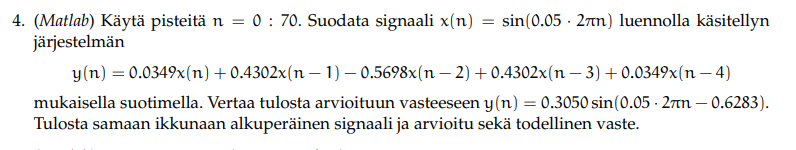

n=0:70

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


x=sin(0.05*2*pi*n)

x =          0    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090


b=[0.0349,0.4302,-0.5698,0.4302,0.0349]%kausaallinen 

b =     0.0349    0.4302   -0.5698    0.4302    0.0349


a=1

a = 1

p=filter(b,a,x)

p =          0    0.0108    0.1535    0.1050    0.1793    0.2467    0.2900    0.3050    0.2900    0.2467    0.1793    0.0942    0.0000   -0.0942   -0.1793   -0.2467   -0.2900   -0.3050   -0.2900   -0.2467   -0.1793   -0.0942   -0.0000    0.0942    0.1793    0.2467    0.2900    0.3050    0.2900    0.2467    0.1793    0.0942    0.0000   -0.0942   -0.1793   -0.2467   -0.2900   -0.3050   -0.2900   -0.2467   -0.1793   -0.0942   -0.0000    0.0942    0.1793    0.2467    0.2900    0.3050    0.2900    0.2467


y=0.3050*sin(0.05*2*pi*n-0.6283)

y =    -0.1793   -0.0942    0.0000    0.0943    0.1793    0.2468    0.2901    0.3050    0.2901    0.2467    0.1793    0.0942   -0.0000   -0.0943   -0.1793   -0.2468   -0.2901   -0.3050   -0.2901   -0.2467   -0.1793   -0.0942    0.0000    0.0943    0.1793    0.2468    0.2901    0.3050    0.2901    0.2467    0.1793    0.0942   -0.0000   -0.0943   -0.1793   -0.2468   -0.2901   -0.3050   -0.2901   -0.2467   -0.1793   -0.0942    0.0000    0.0943    0.1793    0.2468    0.2901    0.3050    0.2901    0.2467


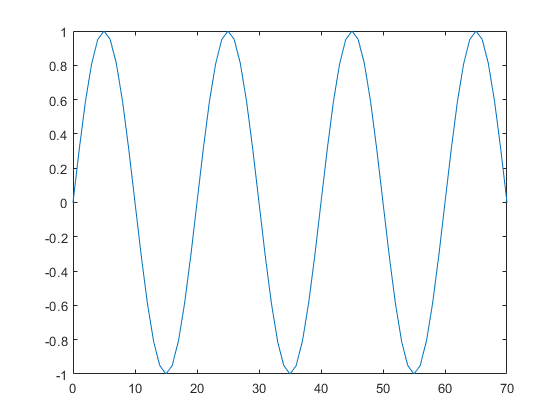

plot(n,x)

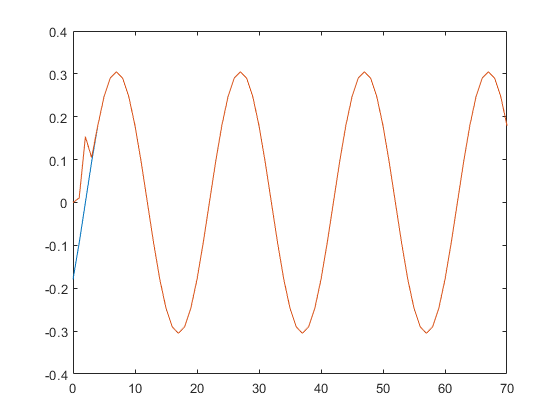

plot(n,y,n,p)

%y=0.0349.*x+0.4302.*x(1,1:70)+0.5698.*x(1,1:69)+0.4302.*x(1,1:68)+0.0349*x(1,1:67)

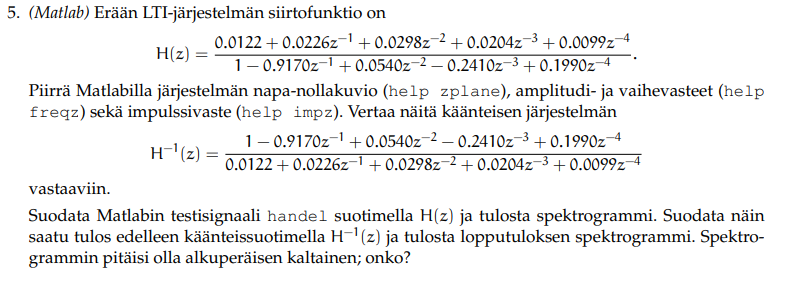

%H
b=[0.0122,0.0226,0.0298,0.0204,0.0099]

b =     0.0122    0.0226    0.0298    0.0204    0.0099


a=[1,-0.9170,0.0540,-0.2410,0.1990]

a =     1.0000   -0.9170    0.0540   -0.2410    0.1990


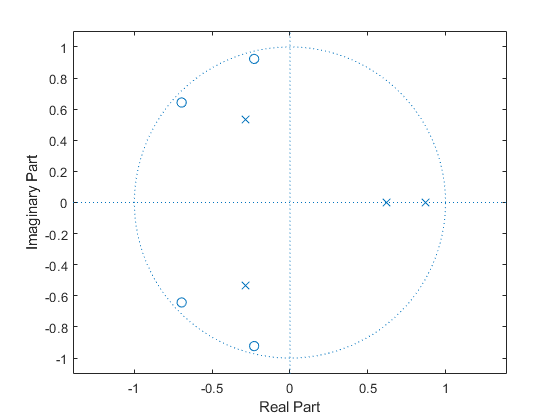

zplane(b,a)

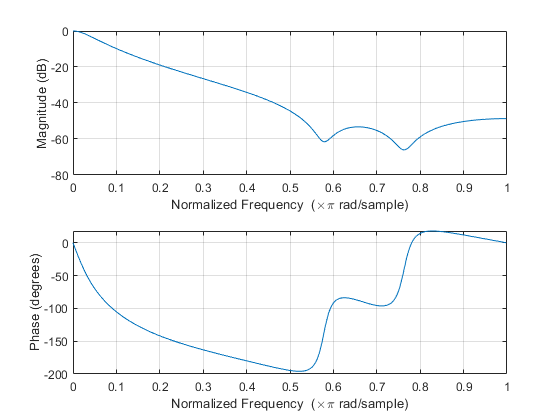

freqz(b,a)

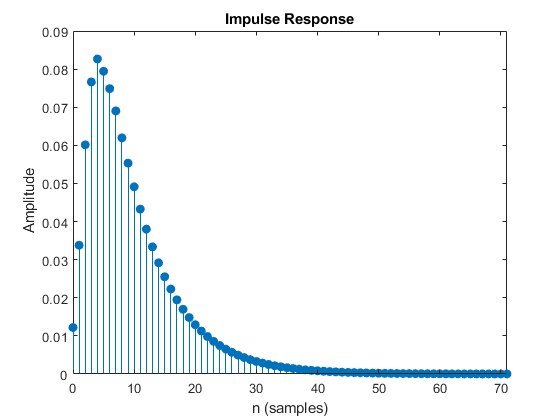

impz(b,a)

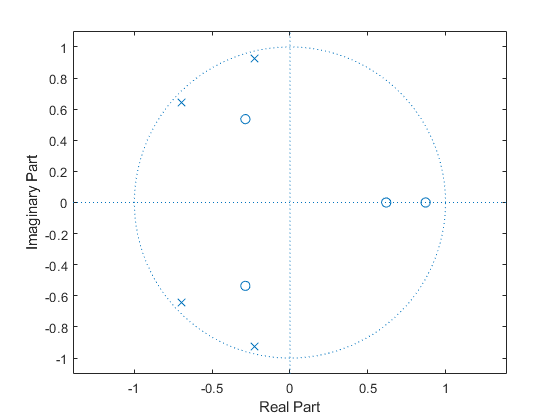

%H^(-1)
zplane(a,b)

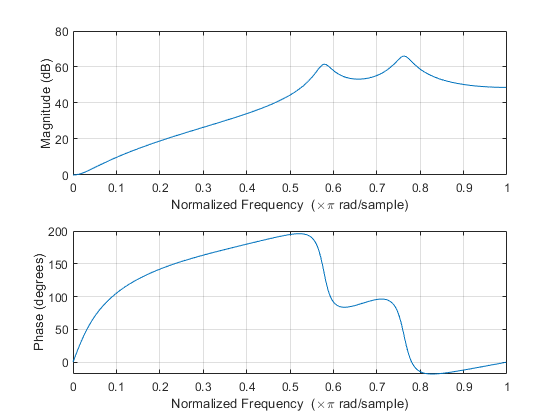

freqz(a,b)

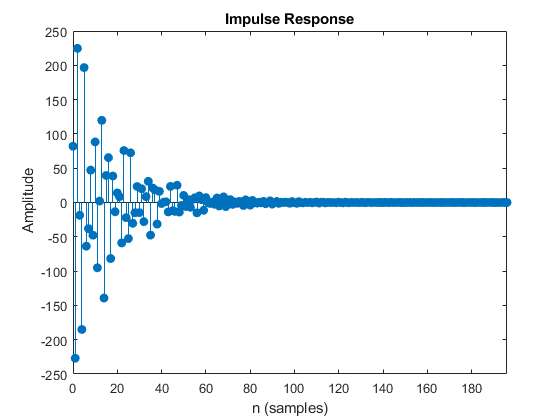

impz(a,b)

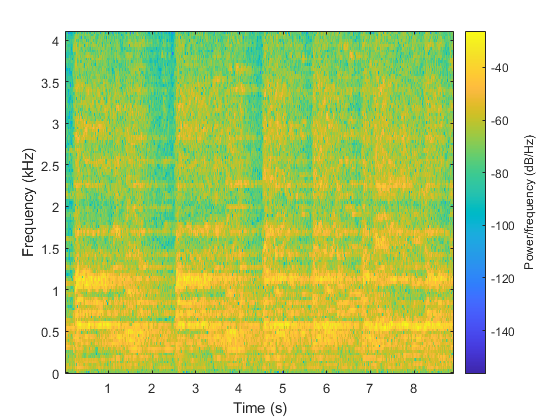

load handel.mat;%y Fs
spectrogram(y,256,[],[],Fs,'yaxis');%y

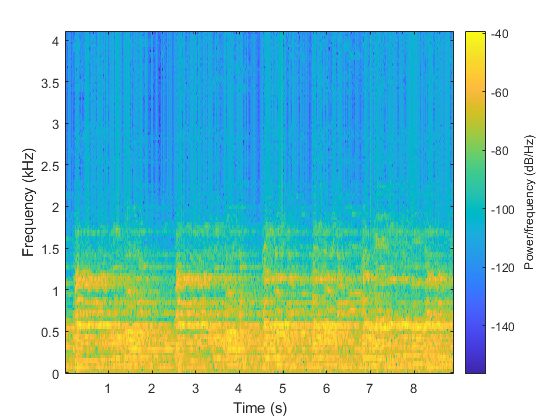

filtered=filter(b,a,y);
spectrogram(filtered,256,[],[],Fs,'yaxis');%H


%%H^-1
filtered=filter(a,b,filtered);
spectrogram(filtered,256,[],[],Fs,'yaxis');%H^-1